# Homework 4

Math 3607, Autumn 2021

Marco LoPiccolo

## Problem 1. 

### a.)

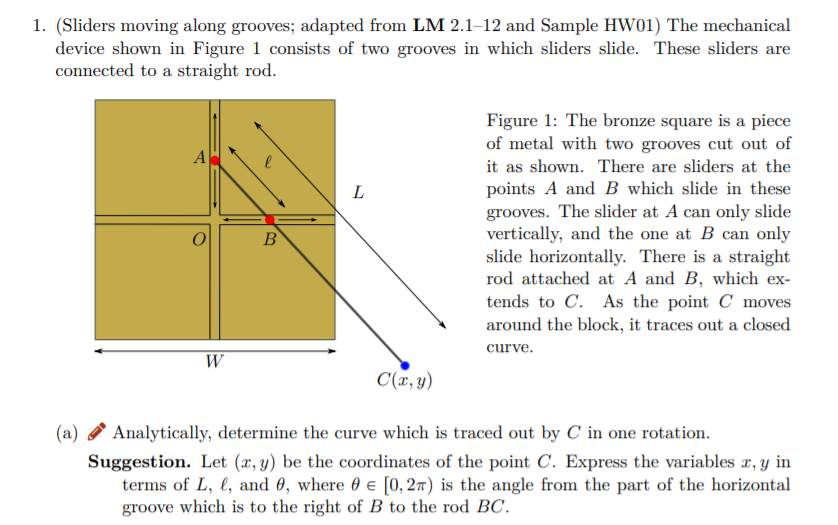

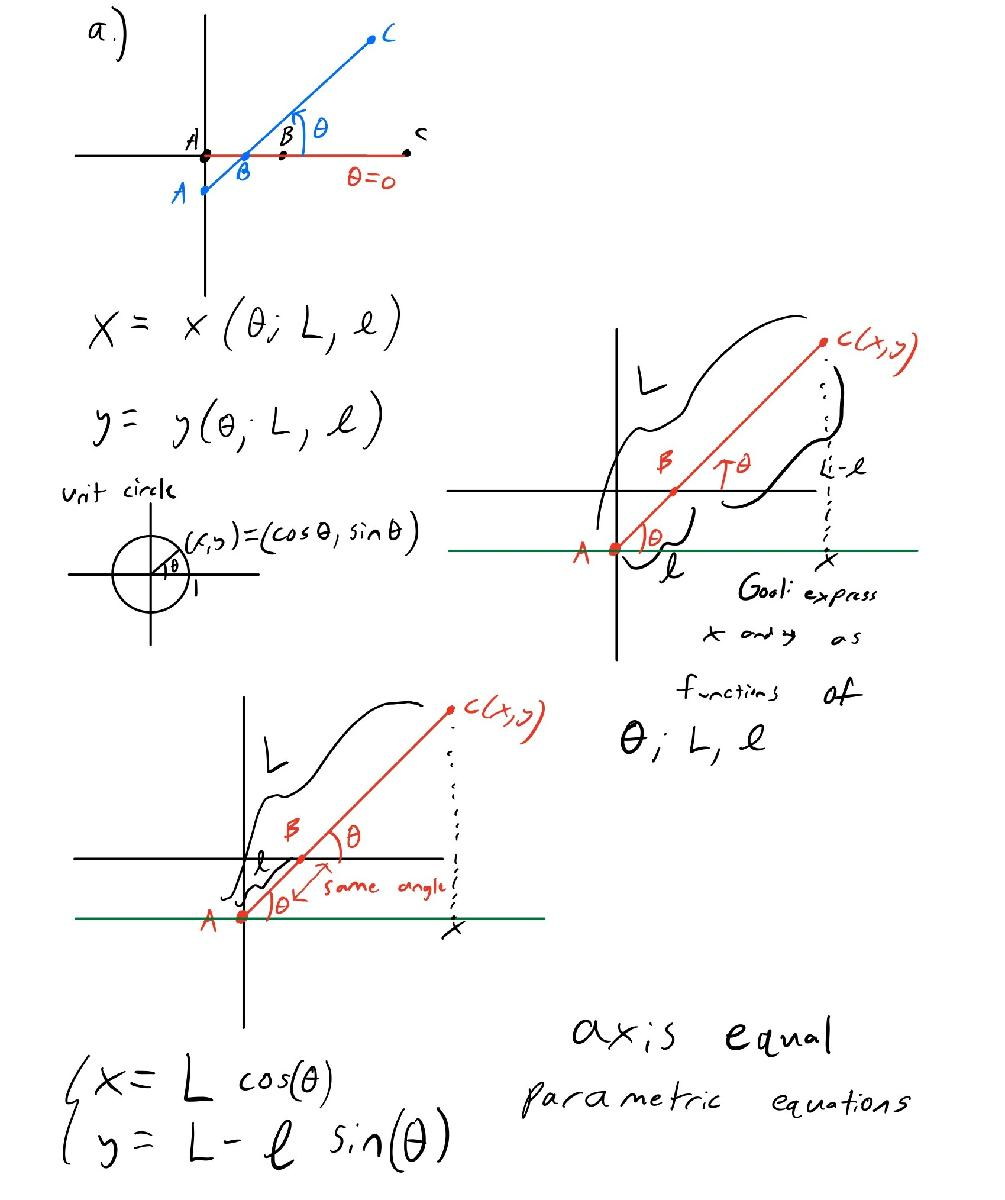

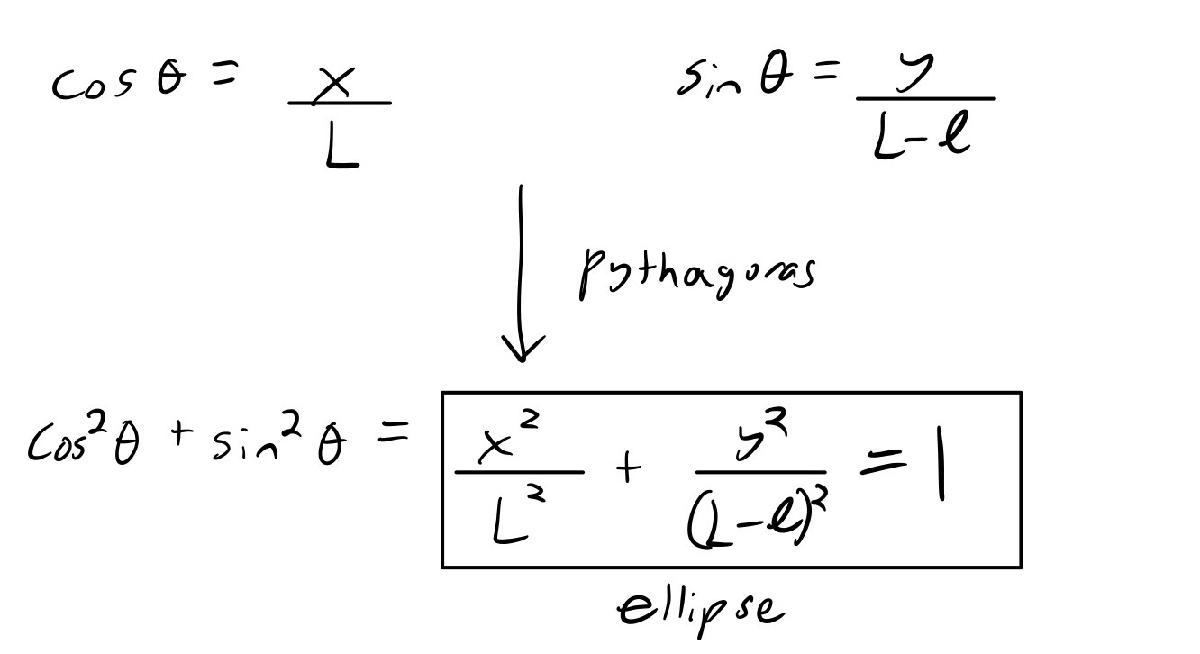

### b.)

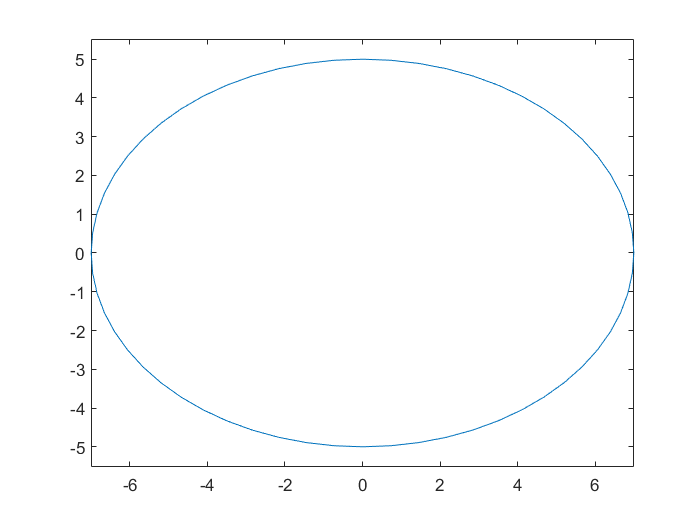

theta = linspace(0, 2*pi, 61);
L = 7;
l = 2;
x = L * cos(theta);
y = (L - l) * sin(theta);
clf
plot(x,y)
axis equal

## Problem 2. 

### a.)

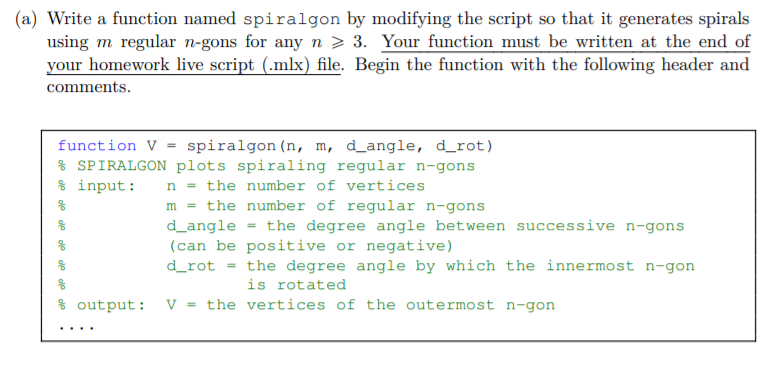

clf
% Test Code, actual function found at the bottom of the live script
% m = 21; d_angle = 4.5; d_rot = 90; n = 10;
% th = linspace(0, 360, n + 1) + d_rot;
% V = [cosd(th);
% sind(th)];
% C = colormap(hsv(m));
% sPre1 = (n - 2) * 180;
% sPre2 = (sPre1 / n) / 2; 
% s = sind((sPre1 - sPre2) - abs(d_angle))/sind(sPre2);
% R = [cosd(d_angle) -sind(d_angle);
% sind(d_angle) cosd(d_angle)];
% hold off
% for i = 1:m
% if i > 1
% V = s*R*V;
% end
% plot(V(1,:), V(2,:), 'Color', C(i,:))
% hold on
% end
% set(gcf, 'Color', 'w')
% axis equal, axis off


### b.)

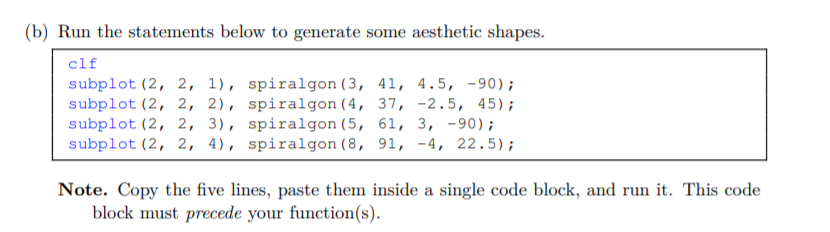

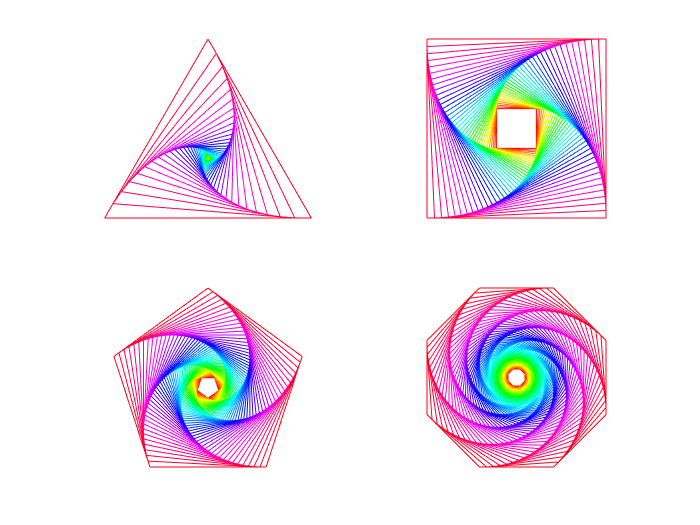

clf
subplot(2, 2, 1), spiralgon(3, 41, 4.5, -90);
subplot(2, 2, 2), spiralgon(4, 37, -2.5, 45);
subplot(2, 2, 3), spiralgon(5, 61, 3, -90);
subplot(2, 2, 4), spiralgon(8, 91, -4, 22.5);

## Problem 3. 

### a.)

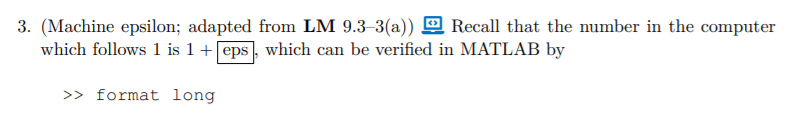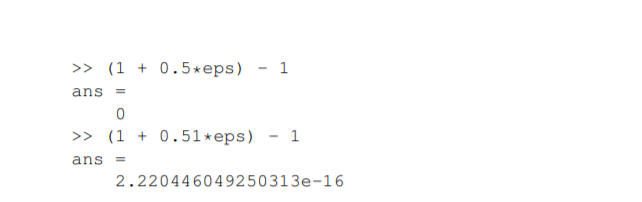

format long
(1 + 0.51*eps) - 1

ans =      2.220446049250313e-16


eps

ans =      2.220446049250313e-16


(8 + 8*eps) - 8

ans =      1.776356839400250e-15


(8 + 4*eps) - 8

ans =      0


(8 + 4.01*eps) - 8

ans =      1.776356839400250e-15


### b.)

(16 - 8*eps) - 16

ans =     -1.776356839400250e-15


(16 - 4.01*eps) - 16

ans =     -1.776356839400250e-15


(16 - 4*eps) - 16

ans =      0


### c.)

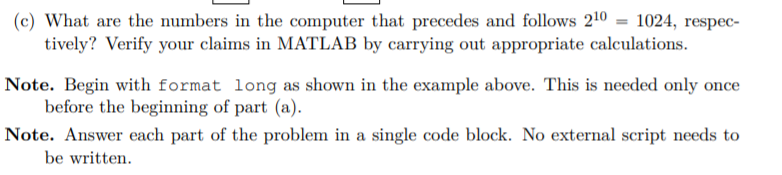

(1024 + 1024*eps) - 1024

ans =      2.273736754432321e-13


(1024 + 512*eps) - 1024

ans =      0


(1024 + 512.01*eps) - 1024

ans =      2.273736754432321e-13


(1024 - 512*eps) - 1024

ans =     -1.136868377216160e-13


(1024 - 256*eps) - 1024

ans =      0


(1024 - 256.01*eps) - 1024

ans =     -1.136868377216160e-13


## Problem 4. 

### a.)

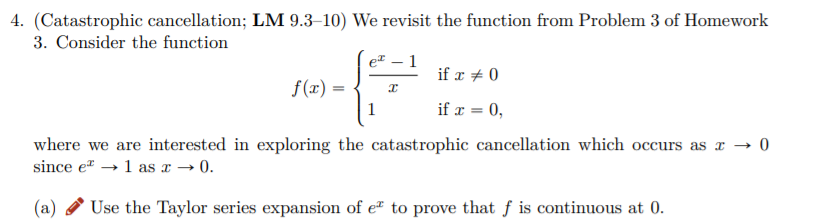

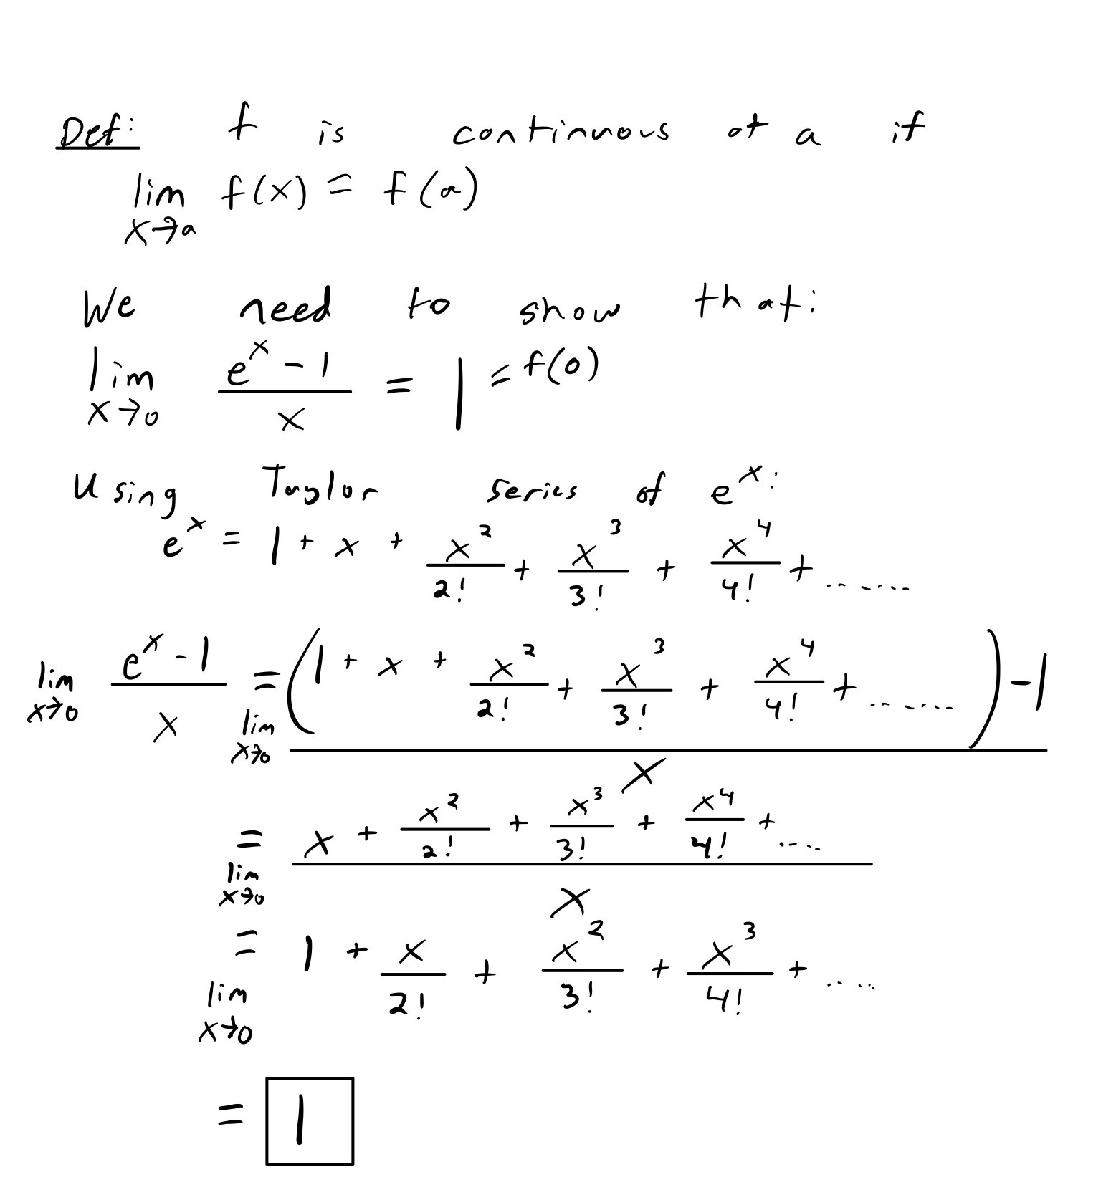

### b.i.)

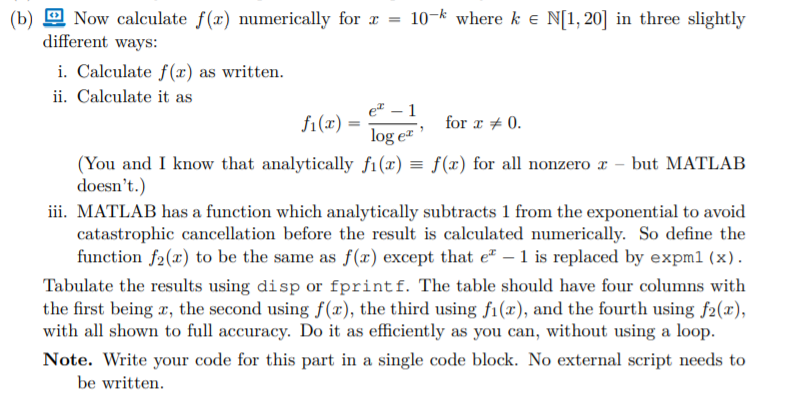

k = [1:20]';
x = 10 .^ -k;
fx = (exp(x) - 1) ./ x;

### b.ii.)

f1x = (exp(x) - 1) ./ (log(exp(x)));

### b.iii.)

f2x = expm1(x) ./ x;
format long 
fprintf('   x                   fx                   f1x                  f2x')

   x                   fx                   f1x                  f2x

fprintf('   ------------------------------------------------------------------')

   ------------------------------------------------------------------

fprintf('%20.16f %20.16f %20.16f %20.16f\n', [x, fx, f1x, f2x]')

  0.1000000000000000   1.0517091807564771   1.0517091807564762   1.0517091807564762
  0.0100000000000000   1.0050167084167949   1.0050167084168058   1.0050167084168058
  0.0010000000000000   1.0005001667083846   1.0005001667083415   1.0005001667083417
  0.0001000000000000   1.0000500016671410   1.0000500016667082   1.0000500016667084
  0.0000100000000000   1.0000050000069649   1.0000050000166667   1.0000050000166667
  0.0000010000000000   1.0000004999621837   1.0000005000001666   1.0000005000001666
  0.0000001000000000   1.0000000494336803   1.0000000500000017   1.0000000500000017
  0.0000000100000000   0.9999999939225290   1.0000000050000000   1.0000000050000002
  0.0000000010000000   1.0000000827403710   1.0000000005000000   1.0000000005000000
  0.0000000001000000   1.0000000827403710   1.0000000000500000   1.0000000000500000
  0.0000000000100000   1.0000000827403710   1.0000000000050000   1.0000000000050000
  0.0000000000010000   1.0000889005823410   1.0000000000005000   1.000000000

### c.)

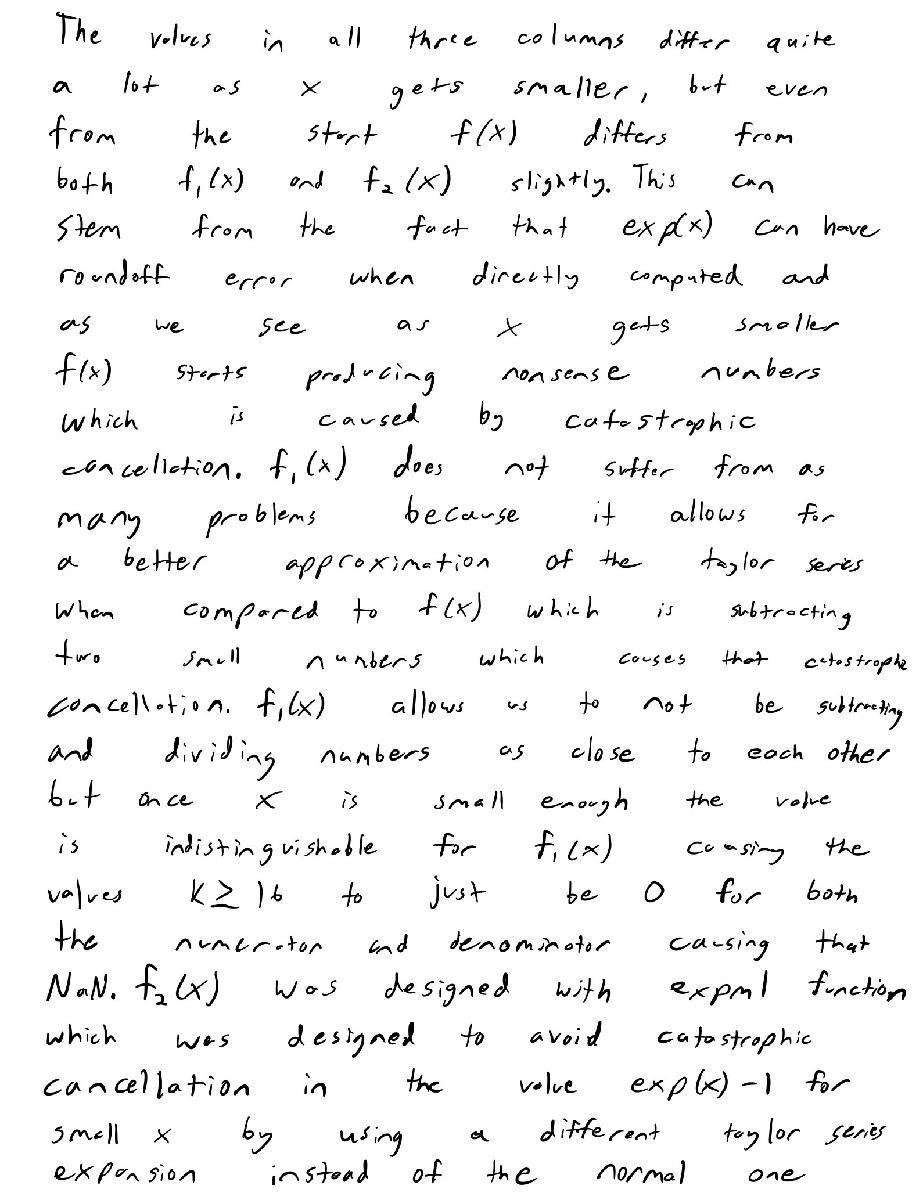

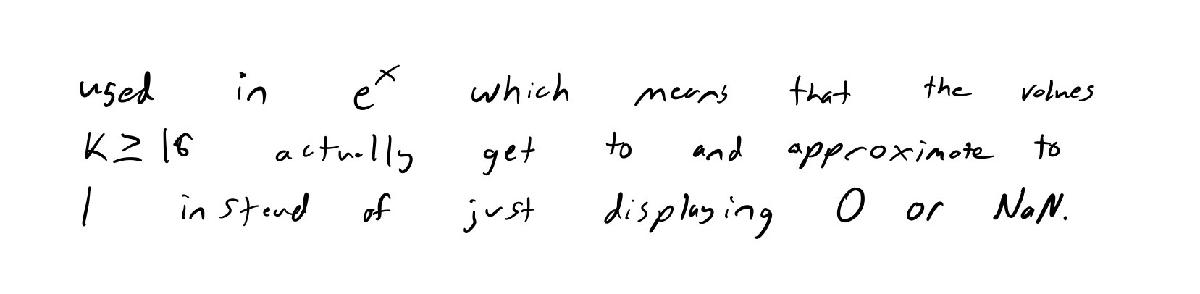

## Problem 5. 

### a.)

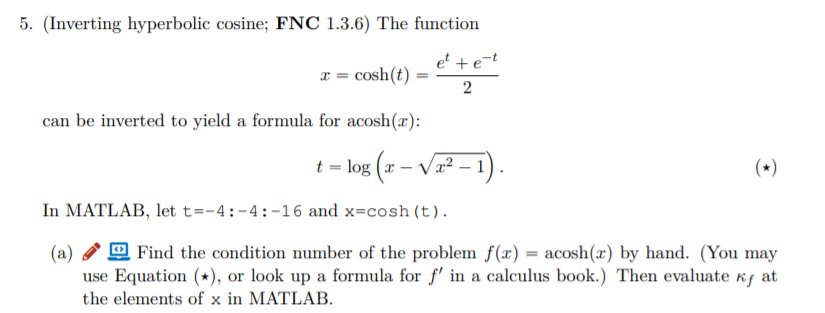

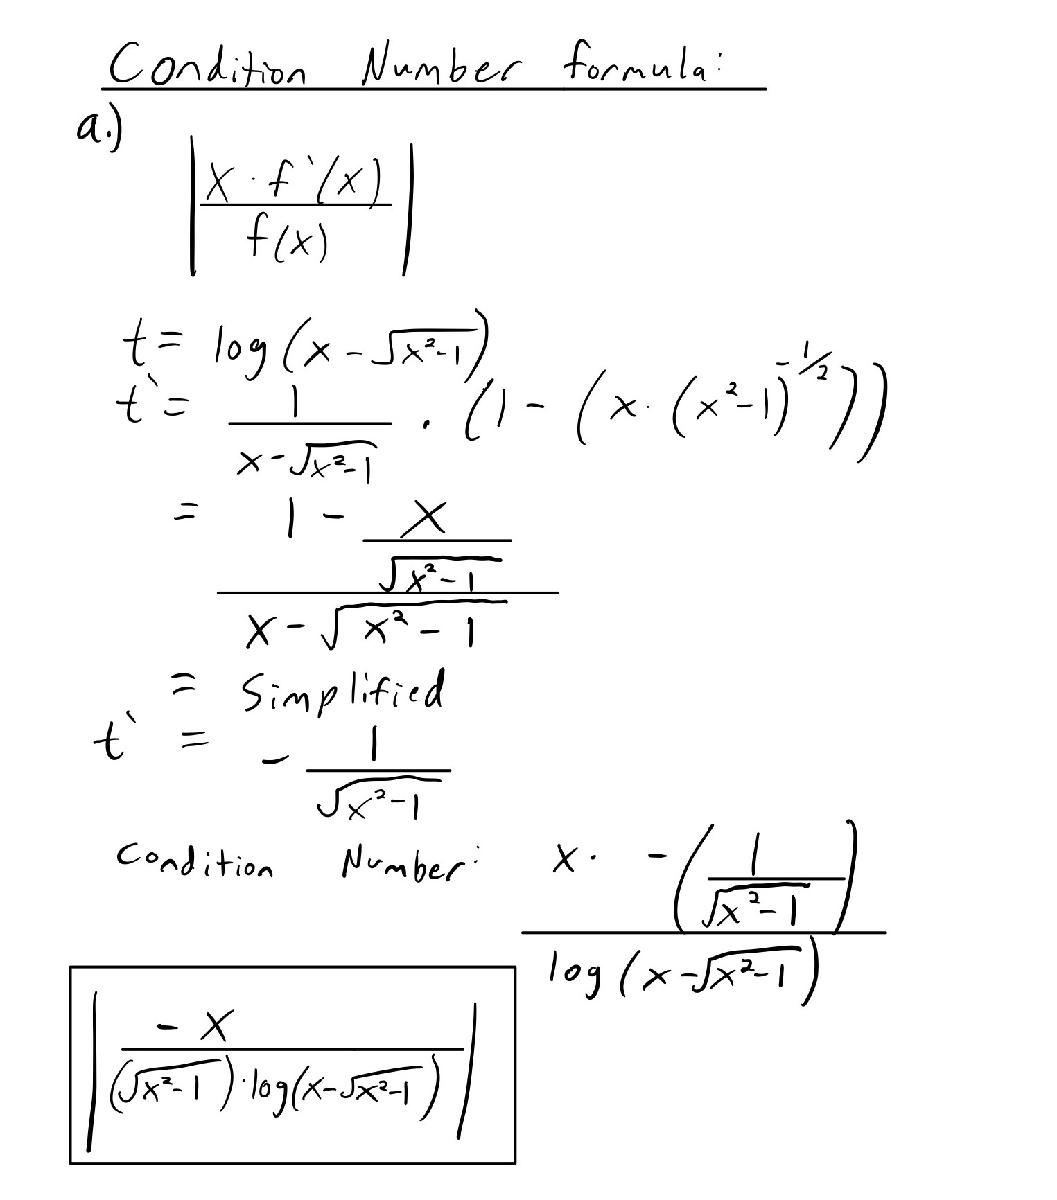

clear
t = (-4:-4:-16)'

t =     -4
    -8
   -12
   -16


x = cosh(t)

x = 	1.0e+06 *

   0.000027308232836
   0.001490479161252
   0.081377395712574
   4.443055260253992


Kf = abs(-x ./ ((sqrt((x .^ 2)-1)) .* log(x-(sqrt((x .^ 2)-1)))))

Kf =    0.250167787600418
   0.125000028131124
   0.083333332387735
   0.062505372058575


### b.)

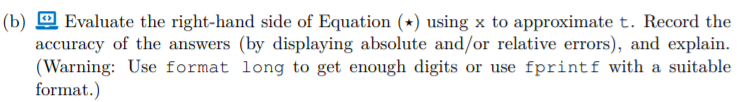

format long
star = log(x-(sqrt((x.^2)-1)));
absErr = star - t;
relErr = absErr ./ t;
fprintf('   t                  star                 absErr              relErr')

   t                  star                 absErr              relErr

fprintf('   ------------------------------------------------------------------')

   ------------------------------------------------------------------

disp([t, star, absErr, relErr])

  -4.000000000000000  -4.000000000000046  -0.000000000000046   0.000000000000012
  -8.000000000000000  -8.000000000171090  -0.000000000171090   0.000000000021386
 -12.000000000000000 -12.000000137072186  -0.000000137072186   0.000000011422682
 -16.000000000000000 -15.998624871201619   0.001375128798381  -0.000085945549899



Based on looking at both t and equation star we see that there are some inconsistencies. While for the first three values of equation star we see that the absolute and relative errors are relatively small but as we go further from -4 it does get larger until at -16 we see that there is a stark difference between the two values and much more significant change in absolute error and relative error. This means that the equation star used for the inversion of the hyperbolic cosine function in matlab struggles to produce t back directly versus acosh which would produce t back directly.

### c.)

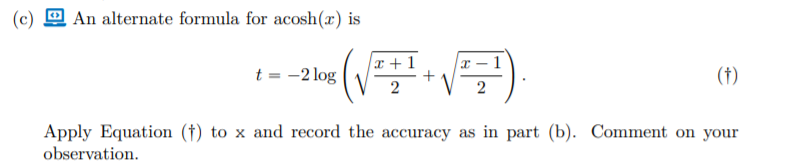

cross = -2 * log((sqrt((x+1)/2))+(sqrt((x-1)/2)));
absErr = cross - t;
relErr = absErr ./ t;
fprintf('   t    star   absErr  relErr')

   t    star   absErr  relErr

fprintf('   ------------------------------------------------------------------')

   ------------------------------------------------------------------

disp([t, cross, absErr, relErr])

    -4    -4     0     0
    -8    -8     0     0
   -12   -12     0     0
   -16   -16     0     0



With this alternative formula we see that it produces the array of t back without any issues and as we see with the absolute error and relative error we see no problems which means that this equation produced a more effective result in matlab compared to the previous equation even though from a theoretical perspective they should produce the same result.

### d.)

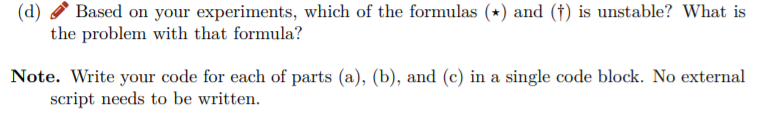

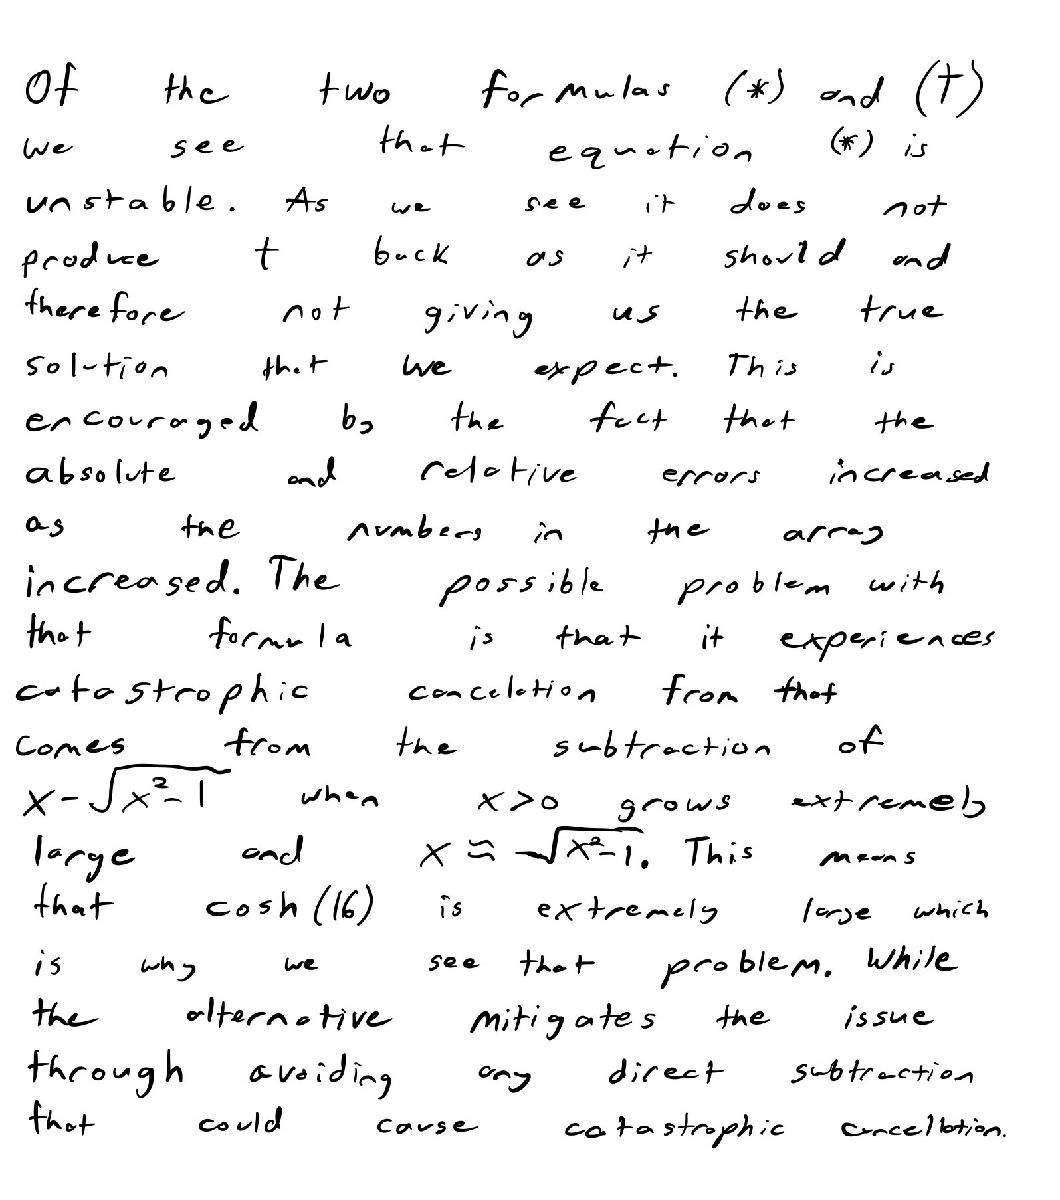

## Functions Used

function V = spiralgon(n, m, d_angle, d_rot)
% SPIRALGON plots spiraling regular n-gons
% input: n = the number of vertices
% m = the number of regular n-gons
% d_angle = the degree angle between successive n-gons
% (can be positive or negative)
% d_rot = the degree angle by which the innermost n-gon
% is rotated
% output: V = the vertices of the outermost n-gon

th = linspace(0, 360, n + 1) + d_rot;         
V = [cosd(th);
    sind(th)];
C = colormap(hsv(m));
sPre1 = (n - 2) * 180;
sPre2 = (sPre1 / n) / 2;
s = sind((sPre1 - sPre2) - abs(d_angle))/sind(sPre2);     
R = [cosd(d_angle) -sind(d_angle);
    sind(d_angle) cosd(d_angle)];
hold off
for i = 1:m
    if i > 1
        V = s*R*V;
    end
    plot(V(1,:), V(2,:), 'Color', C(i,:))
    hold on
end
set(gcf, 'Color', 'w')
axis equal, axis off
end